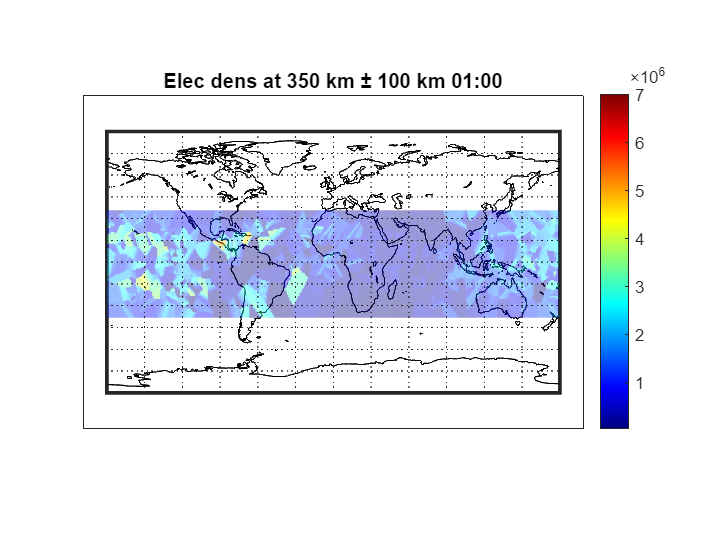

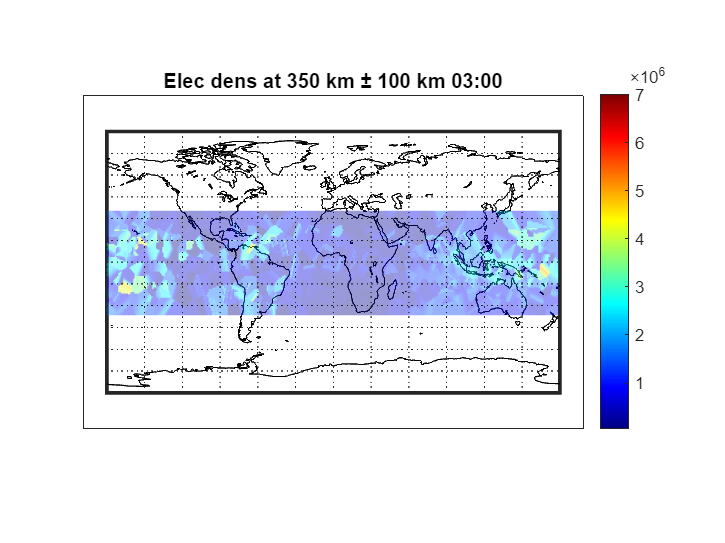

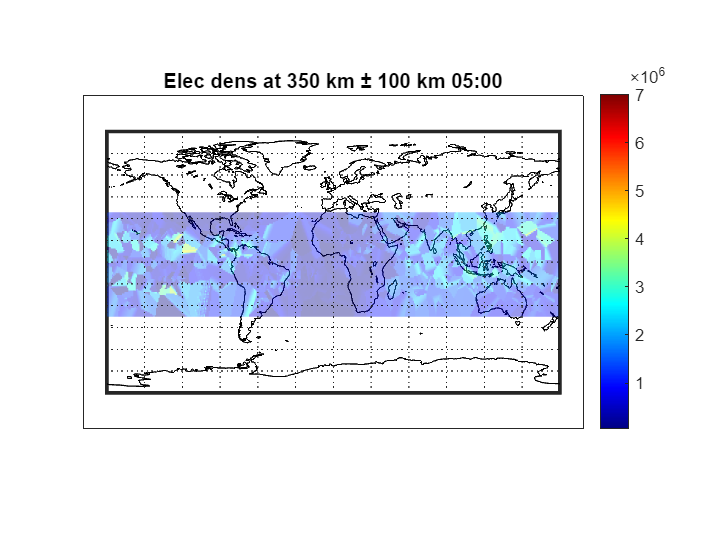

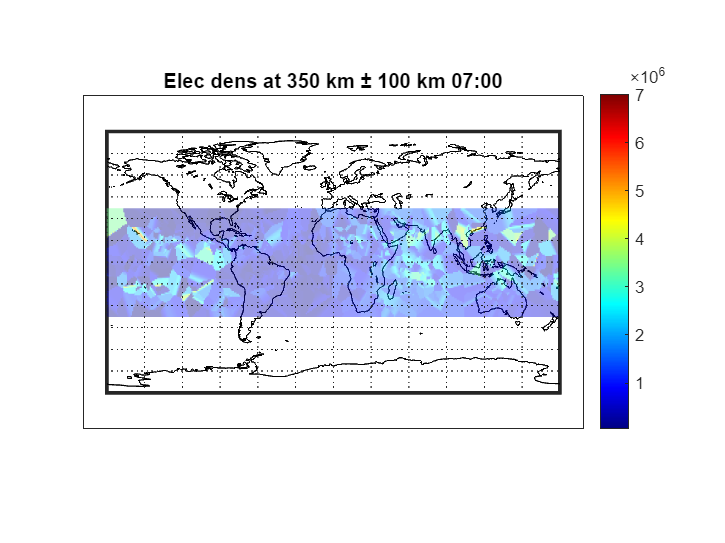

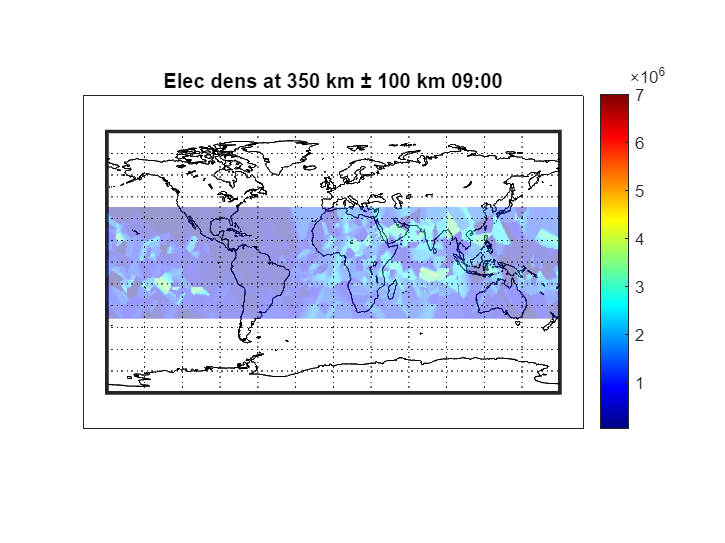

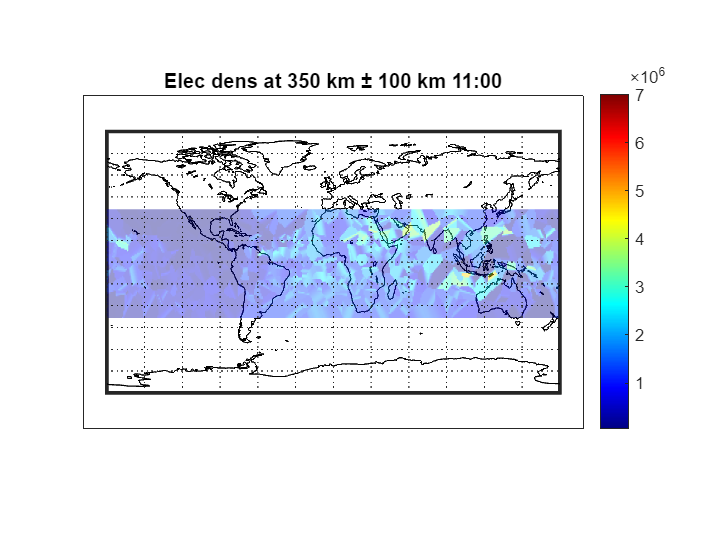

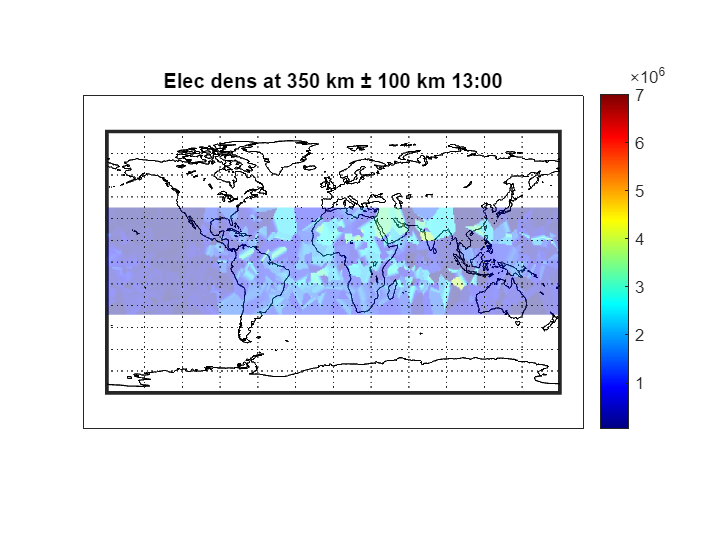

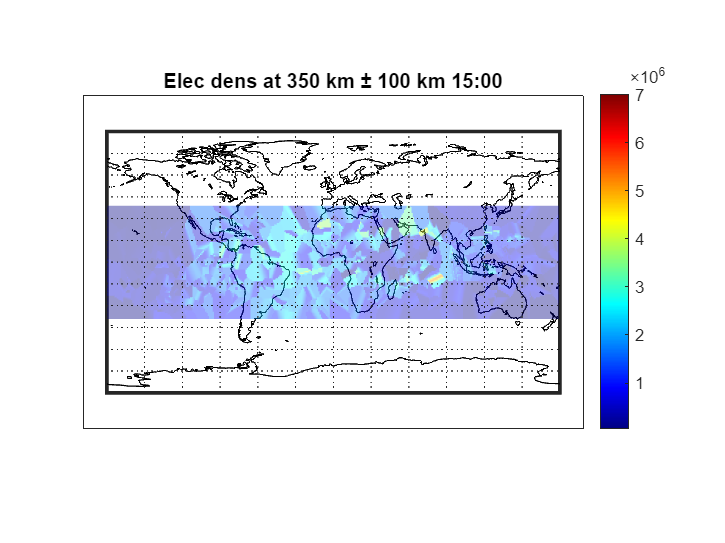

% PLOT_ELECTRON_DENSITY_HEATMAP_GRID - assign nearest ELECTRON DENSITY value to a 2D lat/lon grid and plot


target_altitude = 350;
alt_tolerance = 100;
for target_hour = 1:2:23
%target_hour = 20;
target_minute = 00;
time_tolerance = 60;
grid_res = 1;

%Collect valid points
all_lat = [];
all_lon = [];
all_elec_dens = [];
target_total_minutes = target_hour*60 + target_minute;

for i = 1:length(COSMIC_data)
    ALT = COSMIC_data{i}.MSL_alt(:);
    ELEC_DENS = COSMIC_data{i}.ELEC_dens(:);
    LAT = COSMIC_data{i}.GEO_lat(:);
    LON = COSMIC_data{i}.GEO_lon(:);
    
    file_total_minutes = COSMIC_data{i}.hour*60 + COSMIC_data{i}.minute;
    
    idx = abs(ALT - target_altitude) <= alt_tolerance & ...
          abs(file_total_minutes - target_total_minutes) <= time_tolerance & ...
          ~isnan(ELEC_DENS) & ~isnan(LAT) & ~isnan(LON);
      
    if any(idx)
        all_lat = [all_lat; LAT(idx)];
        all_lon = [all_lon; LON(idx)];
        all_elec_dens = [all_elec_dens; ELEC_DENS(idx)];
    end
end

if isempty(all_lat)
    warning('No points found for this altitude/time window.');
    return
end

% Build 2D grid
lat_vec = (min(all_lat):grid_res:max(all_lat))';
lon_vec = (min(all_lon):grid_res:max(all_lon))';
[LatGrid, LonGrid] = ndgrid(lat_vec, lon_vec);
ELEC_DENSGrid = nan(size(LatGrid));

for r = 1:size(LatGrid,1)
    for c = 1:size(LatGrid,2)
        distances = (all_lat - LatGrid(r,c)).^2 + (all_lon - LonGrid(r,c)).^2;
        [~, idx_min] = min(distances);
        ELEC_DENSGrid(r,c) = all_elec_dens(idx_min);
    end
end

%Plot using Mapping Toolbox

figure

% Create projected map axes
axesm('eqdcylin', ...
      'MapLatLimit', [-90, 90], ...
      'MapLonLimit', [-180, 180], ...
      'Frame','on','Grid','on')

% Add coastlines
load coastlines
geoshow(coastlat, coastlon, 'Color', 'black')

hold on

% Plot the 2D electron density
h = pcolorm(LatGrid, LonGrid, ELEC_DENSGrid);

set(h, 'FaceAlpha', 0.4) 
clim([5e4, 7e6])
colormap(jet)
colorbar

title(sprintf('Elec dens at %.0f km ± %.0f km %02d:%02d', ...
    target_altitude, alt_tolerance, target_hour, target_minute))

hold off
end